Implement a non-unimodal line search method, which terminates when a point satisfying the

Wolfe conditions was found. You may use the code for the Armijo conditions (`Armijo_LS.m`)

as referenceю

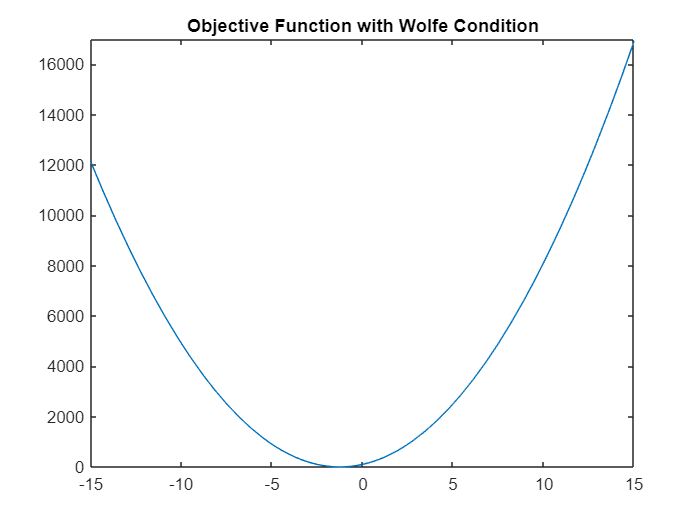

clear
f=@(x) (x+3).^2+2;
df=@(x) 2*x + 6;
x0=1;
iter=10;
cu=0.9;     % curvature parameter
alpha0 = 1; % initial step length

% we could change rho and c in order to see their's effect
rho = 0.5;  % step length multiplier
c = 0.2;    % Armijo condition modifier

result = Armijo_LS_Wolfe(f,df,x0,iter,alpha0,c,cu,rho);

result

result = -13

function x = Armijo_LS_Wolfe(f,df,x0,iter,alpha0,c,cu,rho)
% f  is R->R objective function
% df is derivative
% x0 is starting point
    cnt = 1;
    alpha = alpha0;
    f0 = f(x0);
    df0 = df(x0);
    if df0 > 0
        alpha = -alpha;
    end
    x = x0+alpha;
    fx = f(x);
    dx = df(x);
        while fx < f0 + c*alpha*df0*rho && cnt<=iter && ( abs(dx)*rho > cu*abs(dx)'*rho ) % Wolfe condition
            alpha = alpha/rho;
            x = x0+alpha;
            fx = f(x);
            x0=x; % update the starting point for the next iteration
            cnt = cnt+1;
        end
    xd = @(d) x0+d*alpha;
    fd = @(d) f(xd(d));  % handle the objective function

    figure;
    fplot(fd, [-15,15])
    title('Objective Function with Wolfe Condition');
end